# **HW2 Program Assignment**

**By: 105060012 張育菘**

## P1

Let $x\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack ={\left(0\ldotp 9\right)}^n u\left\lbrack n\right\rbrack$ and $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \ast h\left\lbrack n\right\rbrack$

(a) Determine $y\left\lbrack n\right\rbrack$ analytically and plot the first 99 non-zero samples using the stem function.

close all; clear;
fprintf('1(a)\n');

1(a)


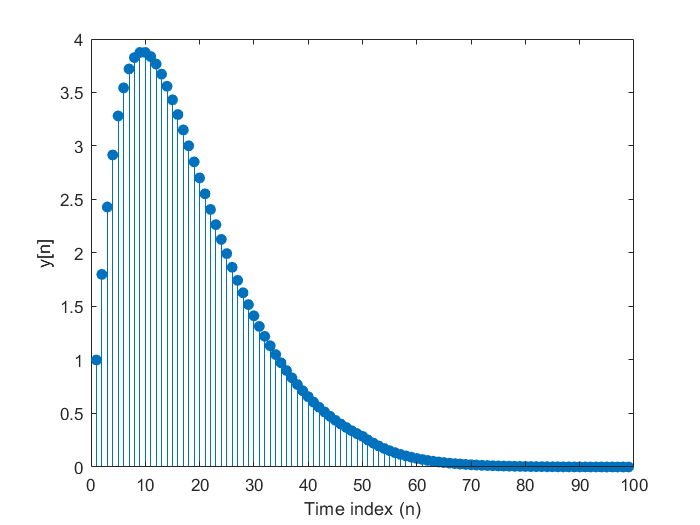

figure
x = zeros(1,99);
h = zeros(1,99);
for i = 1:1:50
    x(i) = 0.9.^(i-1);
end
h = x;
y=zeros(1,99);
for i = 1:1:99
    temp = 0;
    for k = 1:1:i
        temp = temp + x(k).*h(i-k+1);
    end
    y(i) = temp;
end
y1a = y;
n = linspace(1,99,99);
stem(n,y1a,'fill');
ylabel('y[n]');
xlabel('Time index (n)');

(b) Take first 50 samples of $x\left\lbrack n\right\rbrack$ and $h\left\lbrack n\right\rbrack$. Compute and plot $y\left\lbrack n\right\rbrack$ using the conv function. 

fprintf('1(b)\n');

1(b)


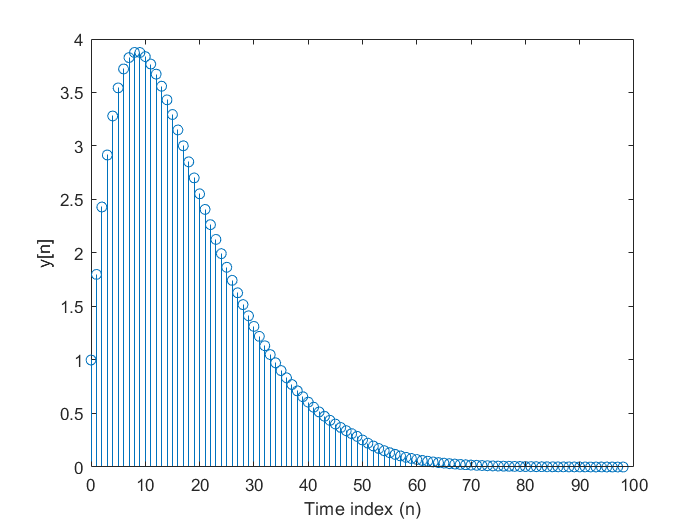

n=linspace(1,50,50);
x = (0.9).^(n-1);
h = (0.9).^(n-1);
y = conv(x,h);
len_y = length(y);
y1b = y;
stem((0:len_y-1),y1b);
ylabel('y[n]');
xlabel('Time index (n)');

(c) Using the filter function, determine and plot the first 99 samples of $y\left\lbrack n\right\rbrack$. 

fprintf('1(c)\n');

1(c)


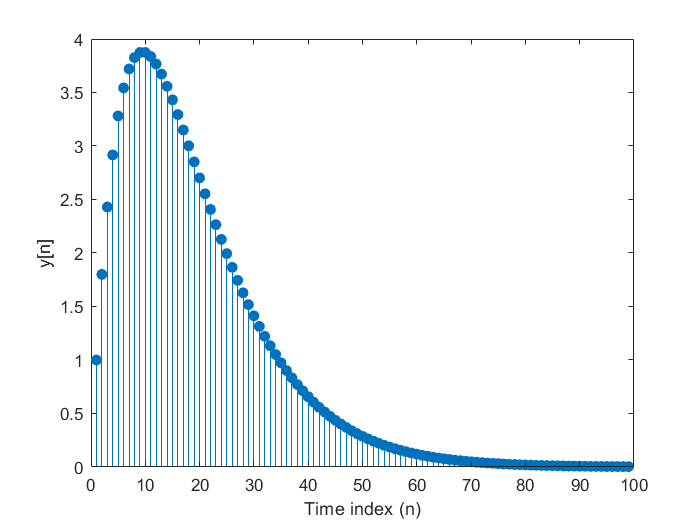

n = linspace(1,99,99);
x_num = 1; x_dem = [1, -0.9];
h = (0.9).^(n-1);
y = filter(x_num,x_dem,h);
y1c = y;
stem(n,y1c,'filled');
ylabel('y[n]');
xlabel('Time index (n)');

(d) Which of the outputs in (b) and (c) come close to that in (a)? Explain. 

Ans.

Compare the value of y between (a) and (b) and (a) and (c), we can find that the value of (b) is closer to (a). 

The reason why is that I use the first 50 samples of x and h for convolution in (a) and (b). However, it uses finite samples of x and h for convolution in (c).

## P2

The sum $A_x \approx \sum_n x\left\lbrack n\right\rbrack$ can be thought of as a measure of the “area” under a sequence $x\left\lbrack n\right\rbrack$.

(a) Starting with the convolution sum (2.36), show that $A_y =A_x A_h$.

Ans.


$$A_x A_h =\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack \sum_{h=-\infty }^{\infty } h\left\lbrack m\right\rbrack =\sum_{n=-\infty }^{\infty } \sum_{m=-\infty }^{\infty } x\left\lbrack n\right\rbrack h\left\lbrack m\right\rbrack =\sum_{n=-\infty }^{\infty } \sum_{k=-\infty }^{\infty } x\left\lbrack n\right\rbrack x\left\lbrack k-n\right\rbrack =\sum_{g=-\infty }^{\infty } y\left\lbrack g\right\rbrack =A_{y\;}$$


(b) x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101); h=ones(1,5); compute $y\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack *x\left\lbrack n\right\rbrack$, check whether $A_y =A_x A_h$.

close all; clear;
fprintf('2(b)\n');

2(b)


x = sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101); 
h = ones(1,5);
y = conv(x,h);
Ay = sum(y,'all');
Ay

Ay = -2.5006

Ax = sum(x,'all');
Ah = sum(h,'all');
AxAh = Ax*Ah

AxAh = -2.5006

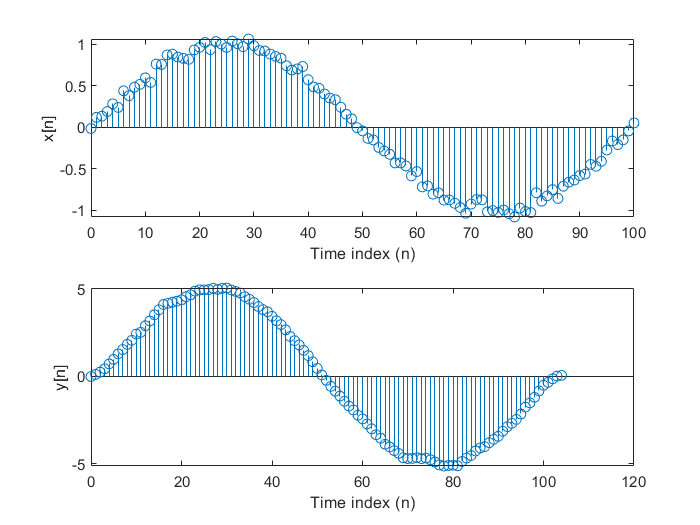

figure
n = linspace(1,1,100);
subplot(2,1,1); stem((0:length(x)-1),x);
ylabel('x[n]');
xlabel('Time index (n)');
subplot(2,1,2); stem((0:length(y)-1),y);
ylabel('y[n]');
xlabel('Time index (n)');

We can find that Ay = Ax*Ah.

(c) Normalize $h\left\lbrack n\right\rbrack$ so that $A_h =1$ and repeat part (b).

fprintf('2(c)\n');

2(c)


x = sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101); 
h = ones(1,5);
h = h/sum(h,'all');
y = conv(x,h);
Ay = sum(y,'all');
Ay

Ay = -0.2632

Ax = sum(x,'all');
Ah = sum(h,'all');
AxAh = Ax*Ah

AxAh = -0.2632

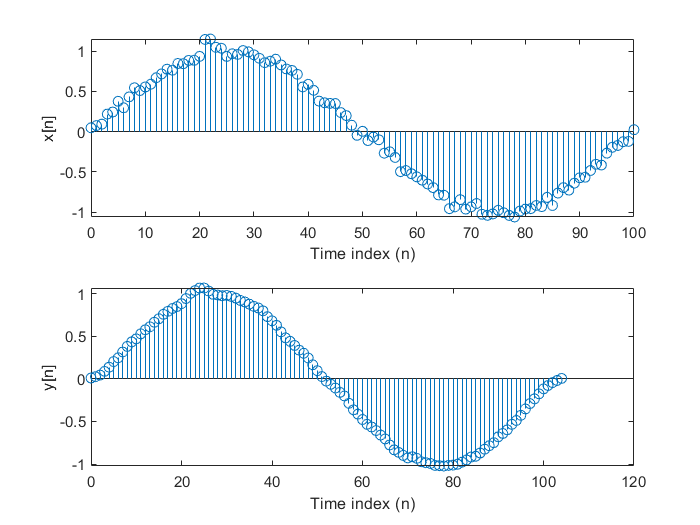

figure
n = linspace(1,1,100);
subplot(2,1,1); stem((0:length(x)-1),x);
ylabel('x[n]');
xlabel('Time index (n)');
subplot(2,1,2); stem((0:length(y)-1),y);
ylabel('y[n]');
xlabel('Time index (n)');

(d) If $A_h =1$, then $A_x =A_y$. Use this result to explain the difference between the plots obtained in parts (b) and (c). 

Ans.

We can find that the values of y in (b) is five times the values of y in (c).

## P3

The response of a LTI system to the input $x\left\lbrack n\right\rbrack =u\left\lbrack n\right\rbrack$ is $y\left\lbrack n\right\rbrack =2{\left(\frac{1}{3}\right)}^n u\left\lbrack n\right\rbrack$

(a) Find the impulse response $h\left\lbrack n\right\rbrack$ of the system, and check the results using the function filter. 


$$X\left(z\right)=\frac{1}{1-z^{-1} \;},Y\left(z\right)=\frac{2}{1-\left(\frac{1}{3}\right)z^{-1} },H\left(z\right)=\frac{6-6z^{-1} }{3-z^{-1} }$$


close all; clear;
fprintf('3(a)\n');

3(a)


num = [6, -6];
dem = [3, -1];
x = ones(1, 20);
%filter: 前兩者為Z-transform，第三者為要filter的訊號in time domain
h = zeros(1, 20); h(1) = 1; %function delta
h_n = filter(num,dem,h)

h_n =     2.0000   -1.3333   -0.4444   -0.1481   -0.0494   -0.0165   -0.0055   -0.0018   -0.0006   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


y_n = filter(num,dem,x)

y_n =     2.0000    0.6667    0.2222    0.0741    0.0247    0.0082    0.0027    0.0009    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


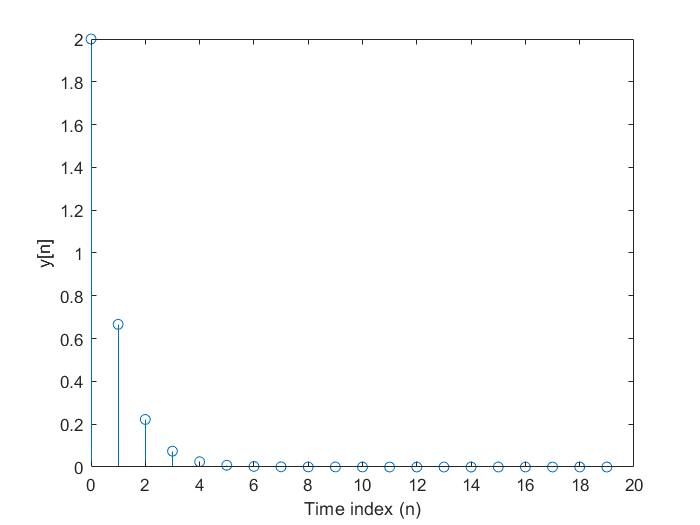

stem((0:length(y_n)-1),y_n);
ylabel('y[n]');
xlabel('Time index (n)');

We can find that the result come from "filter" and the value of the original y[n] are the same.

(b) Plot the pole-zero pattern using the function zplane(b, a). 

fprintf('3(b)\n');

3(b)


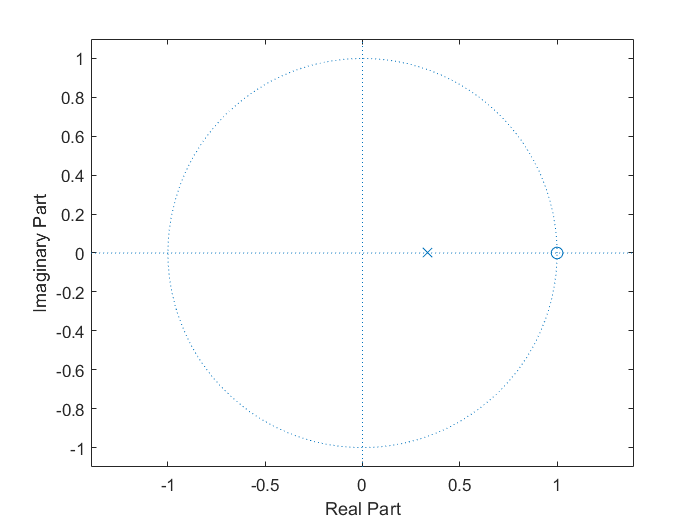

zplane(num,dem);

(c) Compute and plot the impulse response using the functions filter and stem. Compare with the plot obtained using the function impz.

fprintf('3(c)\n');

3(c)


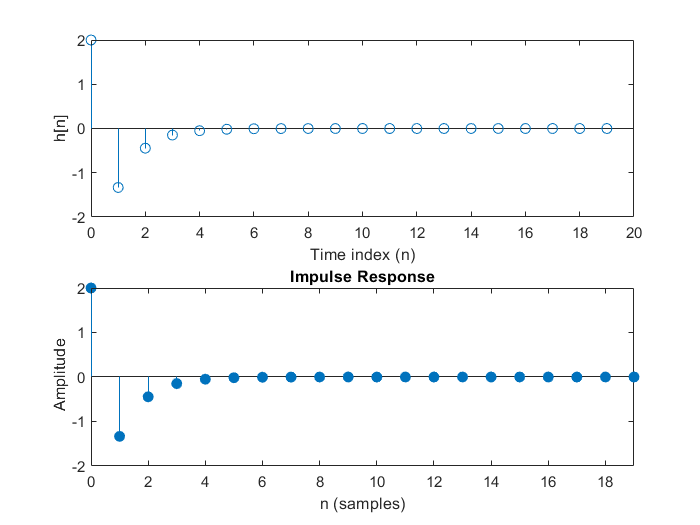

subplot(2,1,1);
h = zeros(1, 20); h(1) = 1;
h_n = filter(num,dem,h);
stem((0:length(h_n)-1),h_n);
ylabel('h[n]');
xlabel('Time index (n)');
subplot(2,1,2);
impz(num, dem, 20)

We can find the result between "filter and stem" and "function impz" are the same.

(d) Use the function residuez and the z-transform pairs in Table 3.1 to find an analytical expression for the impulse response h[n]. 

Ans.

[r1,p1,k1] = residue([6, -6], [3, -1]); $H\left(z\right)=\frac{6-6z^{-1} }{3-z^{-1} }=\mathrm{k1}+\frac{\mathrm{r1}}{z-\mathrm{p1}}$

[r2,p2,k2] = residue([-6, 6], [-1, 3]); 


$$H\left(z\right)=\frac{6-6z^{-1} }{3-z^{-1} }=\mathrm{k2}+\frac{\mathrm{r2}*z}{1-\mathrm{p2}*z}$$

$$\Longrightarrow h\left\lbrack n\right\rbrack =\textrm{k2}*\delta \left\lbrack n\right\rbrack +\left(\frac{-\textrm{r2}}{\textrm{p2}}\right){\left(\frac{1}{\textrm{p2}}\right)}^n u\left\lbrack n\right\rbrack$$


fprintf('3(d)\n');

3(d)


[r,p,k] = residue(fliplr(num), fliplr(dem))

r = 12

p = 3

k = 6

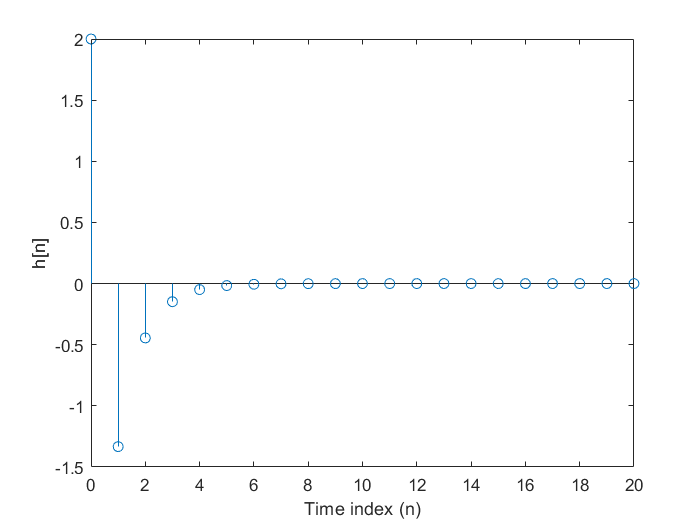

h = zeros(1, 21); h(1)=h(1)+k;
for i = 1:1:21
    h(i) = h(i) + (-r/p).*((1/p).^(i-1));
end
stem((0:length(h)-1),h);
ylabel('h[n]');
xlabel('Time index (n)');


$$\Longrightarrow h\left\lbrack n\right\rbrack =6\delta \left\lbrack n\right\rbrack +\left(-4\right){\left(\frac{1}{3}\right)}^n u\left\lbrack n\right\rbrack$$


## P4

Find the impulse response of the system (3.97) for the case of real and equal poles and use the result to determine how the location of the poles affects (a) the stability of the system, and (b) the shape of the impulse response. 

$H\left(z\right)=\frac{b_0 +b_1 z^{-1} }{1+a_1 z^{-1} +a_2 z^{-2} }=\frac{z\left(b_0 z+b_1 \right)}{z^2 +a_1 z+a_z }$ (3.97)

(Hint: Use MATLAB to replicate Figure 3.10 for a double pole, find C and discuss stability of the three cases $|a_1 |<C,|a_1 |=C,|a_1 |>C$)

(a) 

If this system have real and equal poles, then $z^2 +a_1 z+a_z ={\left(z+c\right)}^2$, and we can get the relationship between $a_1 \;\&\;a_z$ that $4a_z =a_1^2$.

If this system is stable, this means that all poles of this system are inside the unit circle, and we can get the value of $a_1 \;\&\;a_z$ that $a_z =1,|a_1 |<2$ to meet this condition.

(b)

close all; clear;
fprintf('4(b)\n');

4(b)


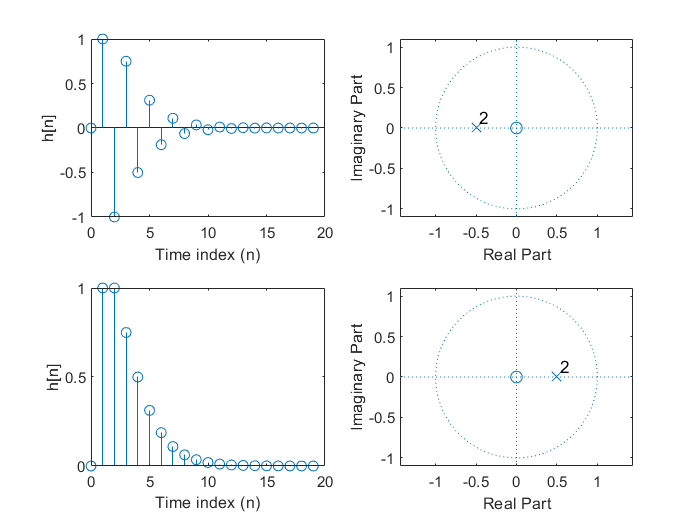


h = zeros(1, 20); h(1) = 1;
b = [0 1];

figure;
a = [1 1 0.25];
subplot(2,2,1);
h_n = filter(b,a,h);
stem((0:length(h_n)-1),h_n);
ylabel('h[n]');
xlabel('Time index (n)');
subplot(2,2,2);
zplane(b,a);

a = [1 -1 0.25];
subplot(2,2,3);
h_n = filter(b,a,h);
stem((0:length(h_n)-1),h_n);
ylabel('h[n]');
xlabel('Time index (n)');
subplot(2,2,4);
zplane(b,a);

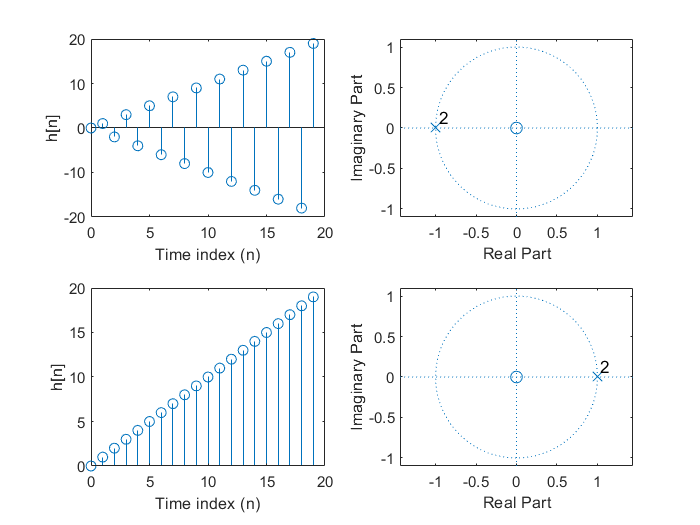


figure;
a = [1 2 1];
subplot(2,2,1);
h_n = filter(b,a,h);
stem((0:length(h_n)-1),h_n);
ylabel('h[n]');
xlabel('Time index (n)');
subplot(2,2,2);
zplane(b,a);

a = [1 -2 1];
subplot(2,2,3);
h_n = filter(b,a,h);
stem((0:length(h_n)-1),h_n);
ylabel('h[n]');
xlabel('Time index (n)');
subplot(2,2,4);
zplane(b,a);

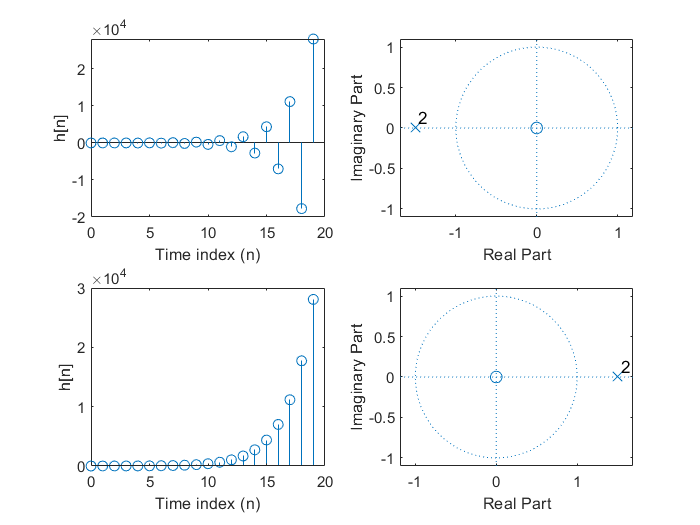


figure;
a = [1 3 2.25];
subplot(2,2,1);
h_n = filter(b,a,h);
stem((0:length(h_n)-1),h_n);
ylabel('h[n]');
xlabel('Time index (n)');
subplot(2,2,2);
zplane(b,a);

a = [1 -3 2.25];
subplot(2,2,3);
h_n = filter(b,a,h);
stem((0:length(h_n)-1),h_n);
ylabel('h[n]');
xlabel('Time index (n)');
subplot(2,2,4);
zplane(b,a);

After observing the result of shapes of the impulse response, we can find that the two poles system is stable if two poles locate in the unit circle. Morever, if two poles locate at left-half plane (real value<0), the asymptote of h[n] are positive and negative equations. 

## P5

Consider the following LCCDE: $y\left\lbrack n\right\rbrack =2\mathrm{cos}\left(\omega_0 \right)y\left\lbrack n-1\right\rbrack -y\left\lbrack n-2\right\rbrack$, with no input but with initial conditions $y\left\lbrack -1\right\rbrack =0$ and $y\left\lbrack -2\right\rbrack =-\mathrm{Asin}\left(\omega_0 \right)$. 

(a) Show that the solution of the above LCCDE is given by the sequence$y\left\lbrack n\right\rbrack =\textrm{Asin}\left\lbrack \left(n+1\right)\omega_0 \right\rbrack u\left\lbrack n\right\rbrack$. This system is known as a digital oscillator (derive in the live script). 

Ans. 

- It's true for n = 0, n = 1, and n = 2, $y\left\lbrack 0\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack -1\right\rbrack -y\left\lbrack -2\right\rbrack =\textrm{Asin}\left(\omega_0 \right)=\textrm{Asin}\left\lbrack \left(0+1\right)\omega_0 \right\rbrack$, $y\left\lbrack 1\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack 0\right\rbrack -y\left\lbrack -1\right\rbrack =2\textrm{Asin}\left(\omega_0 \right)\cos \left(\omega_0 \right)=\textrm{Asin}\left\lbrack \left(1+1\right)\omega_0 \right\rbrack$, $y\left\lbrack 2\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack 1\right\rbrack -y\left\lbrack 0\right\rbrack =\textrm{A}\left\lbrack \sin \left(2\omega_0 \right)\cos \left(\omega_0 \right)+\mathrm{sin}\left(\omega_0 \right)\left(2\;{\mathrm{cos}}^2 \left(\omega_0 \right)-1\right)\right\rbrack =\textrm{Asin}\left\lbrack \left(2+1\right)\omega_0 \right\rbrack$

- Assume it's true for n = k (>0), $y\left\lbrack k\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack k-1\right\rbrack -y\left\lbrack k-2\right\rbrack =\textrm{Asin}\left\lbrack \left(k+1\right)\omega_0 \right\rbrack$

- For n = k+1, $y\left\lbrack k\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack k-1\right\rbrack -y\left\lbrack k-2\right\rbrack =2\cos \left(\omega_0 \right)\textrm{Asin}\left(k\omega_0 \right)-\textrm{Asin}\left(\left(k-1\right)\omega_0 \right)=\textrm{Asin}\left\lbrack \left(\left(k+1\right)+1\right)\omega_0 \right\rbrack$

- By Mathematical Induction, we can state that "$y\left\lbrack n\right\rbrack =2\cos \left(\omega_0 \right)y\left\lbrack n-1\right\rbrack -y\left\lbrack n-2\right\rbrack$ with $y\left\lbrack -1\right\rbrack =0$ and $y\left\lbrack -2\right\rbrack =-\mathrm{Asin}\left(\omega_0 \right)$" is the same as "$y\left\lbrack n\right\rbrack =\textrm{Asin}\left\lbrack \left(n+1\right)\omega_0 \right\rbrack u\left\lbrack n\right\rbrack$".

(b) For A = 2 and $\omega_0 =0\ldotp 1\pi$, verify the operation of the above digital oscillator using the filtic and the filter function. (Hint: Check one-sided z-transform in supplement) 

close all; clear;
fprintf('5(b)\n');

5(b)


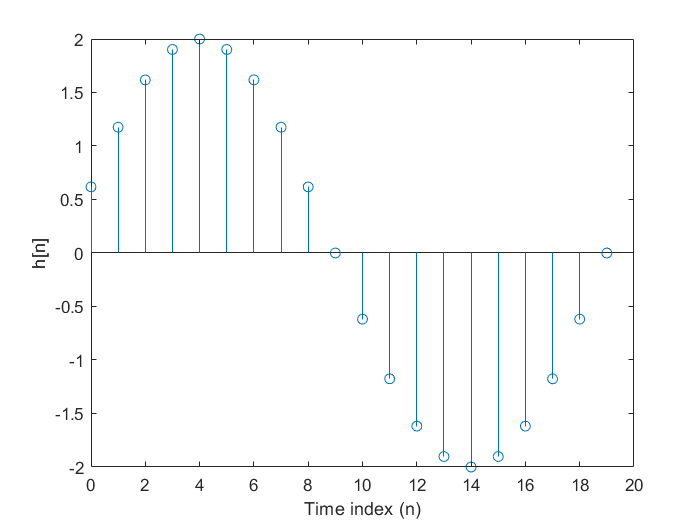


A = 2; w0 = (0.1)*pi;

del = zeros(1, 20); del(1) = 1; %delta function
b = [0 0 0]; a = [1 -2*cos(w0) 1];
xic = [0 0]; yic = [0 -A*sin(w0)];
% Calculate the zero input initial conditions for the system.
hic = filtic(b, a, yic, xic); 
% uses initial conditions hic for the filter delays.
h = filter(b, a, del, hic); 

stem((0:length(h)-1), h);
ylabel('h[n]');
xlabel('Time index (n)');

## P6

In this problem we illustrate the numerical evaluation of DTFS using MATLAB. 

(a) Write a function c=dtfs0(x) which computes the DTFS coefficients (4.67) of a periodic signal and verify the result with dtfs function. 


$$c_k =\frac{1}{N}\sum_{n\;=\;0}^{N-1} x\left\lbrack n\right\rbrack e^{-j\;\frac{2\pi }{\;N}\mathrm{kn}}$$


close all; clear;
fprintf('6(a)\n');

6(a)


x = sin(2*pi*0.05*(0:100))

x =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


c_dtfs0 = dtfs0(x)

c_dtfs0 =   -0.0000 + 0.0000i   0.0001 - 0.0020i   0.0003 - 0.0046i   0.0008 - 0.0090i   0.0026 - 0.0208i   0.0767 - 0.4894i  -0.0053 + 0.0280i  -0.0032 + 0.0145i  -0.0026 + 0.0101i  -0.0023 + 0.0078i  -0.0021 + 0.0064i  -0.0020 + 0.0055i  -0.0019 + 0.0048i  -0.0018 + 0.0042i  -0.0018 + 0.0038i  -0.0017 + 0.0035i  -0.0017 + 0.0032i  -0.0017 + 0.0029i  -0.0017 + 0.0027i  -0.0017 + 0.0025i  -0.0016 + 0.0023i  -0.0016 + 0.0021i  -0.0016 + 0.0020i  -0.0016 + 0.0019i  -0.0016 + 0.0017i  -0.0016 + 0.0016i  -0.0016 + 0.0015i  -0.0016 + 0.0014i  -0.0016 + 0.0013i  -0.0016 + 0.0013i  -0.0016 + 0.0012i  -0.0016 + 0.0011i  -0.0016 + 0.0010i  -0.0016 + 0.0010i  -0.0016 + 0.0009i  -0.0016 + 0.0008i  -0.0016 + 0.0008i  -0.0016 + 0.0007i  -0.0016 + 0.0006i  -0.0016 + 0.0006i  -0.0016 + 0.0005i  -0.0016 + 0.0005i  -0.0016 + 0.0004i  -0.0016 + 0.0004i  -0.0016 + 0.0003i  -0.0016 + 0.0003i  -0.0016 + 0.0002i  -0.0016 + 0.0002i  -0.0016 + 0.0001i  -0.0016 + 0.0001i


c_dtfs = dtfs(x)

c_dtfs =   -0.0000 + 0.0000i   0.0001 - 0.0020i   0.0003 - 0.0046i   0.0008 - 0.0090i   0.0026 - 0.0208i   0.0767 - 0.4894i  -0.0053 + 0.0280i  -0.0032 + 0.0145i  -0.0026 + 0.0101i  -0.0023 + 0.0078i  -0.0021 + 0.0064i  -0.0020 + 0.0055i  -0.0019 + 0.0048i  -0.0018 + 0.0042i  -0.0018 + 0.0038i  -0.0017 + 0.0035i  -0.0017 + 0.0032i  -0.0017 + 0.0029i  -0.0017 + 0.0027i  -0.0017 + 0.0025i  -0.0016 + 0.0023i  -0.0016 + 0.0021i  -0.0016 + 0.0020i  -0.0016 + 0.0019i  -0.0016 + 0.0017i  -0.0016 + 0.0016i  -0.0016 + 0.0015i  -0.0016 + 0.0014i  -0.0016 + 0.0013i  -0.0016 + 0.0013i  -0.0016 + 0.0012i  -0.0016 + 0.0011i  -0.0016 + 0.0010i  -0.0016 + 0.0010i  -0.0016 + 0.0009i  -0.0016 + 0.0008i  -0.0016 + 0.0008i  -0.0016 + 0.0007i  -0.0016 + 0.0006i  -0.0016 + 0.0006i  -0.0016 + 0.0005i  -0.0016 + 0.0005i  -0.0016 + 0.0004i  -0.0016 + 0.0004i  -0.0016 + 0.0003i  -0.0016 + 0.0003i  -0.0016 + 0.0002i  -0.0016 + 0.0002i  -0.0016 + 0.0001i  -0.0016 + 0.0001i


The results come from both dtfs0 and dtfs are the same.

(b) Write a function x=idtfs0(c) which computes the inverse DTFS (4.63) and verify the result with idtfs function.


$$x\left\lbrack n\right\rbrack =\sum_{k\;=\;0}^{N-1} c_k e^{j\;\frac{2\pi }{\;N}\mathrm{kn}}$$


fprintf('6(b)\n');

6(b)


c_k = c_dtfs;
x_idtfs0 = idtfs0(c_k)

x_idtfs0 =   -0.0000 + 0.0000i   0.3090 - 0.0000i   0.5878 - 0.0000i   0.8090 - 0.0000i   0.9511 - 0.0000i   1.0000 - 0.0000i   0.9511 - 0.0000i   0.8090 - 0.0000i   0.5878 - 0.0000i   0.3090 - 0.0000i  -0.0000 + 0.0000i  -0.3090 - 0.0000i  -0.5878 + 0.0000i  -0.8090 + 0.0000i  -0.9511 + 0.0000i  -1.0000 + 0.0000i  -0.9511 + 0.0000i  -0.8090 + 0.0000i  -0.5878 + 0.0000i  -0.3090 + 0.0000i   0.0000 - 0.0000i   0.3090 + 0.0000i   0.5878 + 0.0000i   0.8090 - 0.0000i   0.9511 - 0.0000i   1.0000 - 0.0000i   0.9511 - 0.0000i   0.8090 - 0.0000i   0.5878 - 0.0000i   0.3090 - 0.0000i  -0.0000 - 0.0000i  -0.3090 + 0.0000i  -0.5878 + 0.0000i  -0.8090 - 0.0000i  -0.9511 + 0.0000i  -1.0000 - 0.0000i  -0.9511 + 0.0000i  -0.8090 - 0.0000i  -0.5878 + 0.0000i  -0.3090 + 0.0000i   0.0000 + 0.0000i   0.3090 - 0.0000i   0.5878 + 0.0000i   0.8090 - 0.0000i   0.9511 + 0.0000i   1.0000 - 0.0000i   0.9511 - 0.0000i   0.8090 - 0.0000i   0.5878 - 0.0000i   0.3090 + 0.0000i


x_idtfs = idtfs(c_k)

x_idtfs =    -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


The results come from both idtfs0 and idtfs are the same.

## P7

Determine and plot the magnitude and phase spectra of the following periodic sequences: 

(a) $x_1 \left\lbrack n\right\rbrack =4*\mathrm{cos}\left(1\ldotp 2\pi n+\frac{\pi }{3}\right)+6*\mathrm{sin}\left(0\ldotp 4\pi n-\frac{\pi }{6}\right)$

close all; clear;
fprintf('7(a)\n');

7(a)


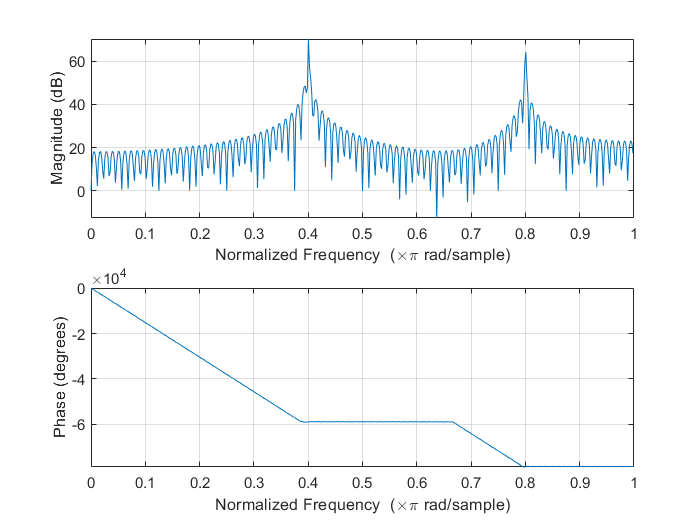

n = 0:50000;
x1 = 4*cos((1.2*pi*n)+(pi/3)) + 6*sin((0.4*pi*n)-(pi/6));
freqz(x1, 1)

(b) $x_2 \left\lbrack n\right\rbrack =\left\lbrace 1,1,0,1,1,1,0,1\right\rbrace ,\left(\mathrm{one}\;\mathrm{period}\right)$

fprintf('7(b)\n');

7(b)


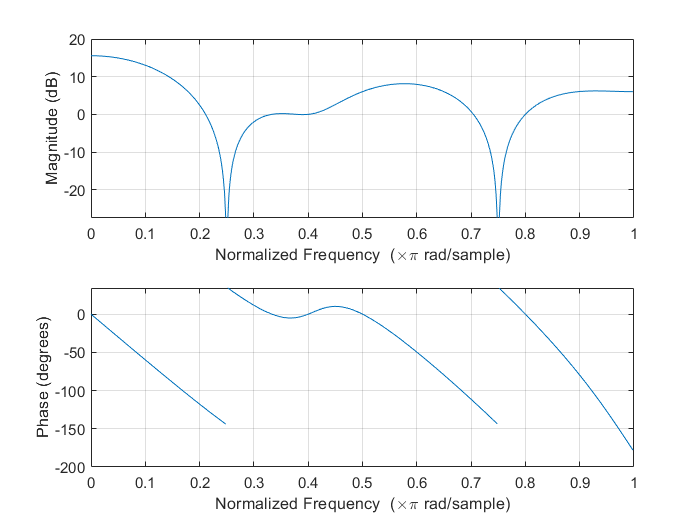

x2 = [1 1 0 1 1 1 0 1];
freqz(x2, 1)

(c) $x_3 \left\lbrack n\right\rbrack =1-\mathrm{sin}\left(\frac{\pi }{4}n\right),0\le n\le 11\;\left(\mathrm{one}\;\mathrm{period}\right)$

fprintf('7(c)\n');

7(c)


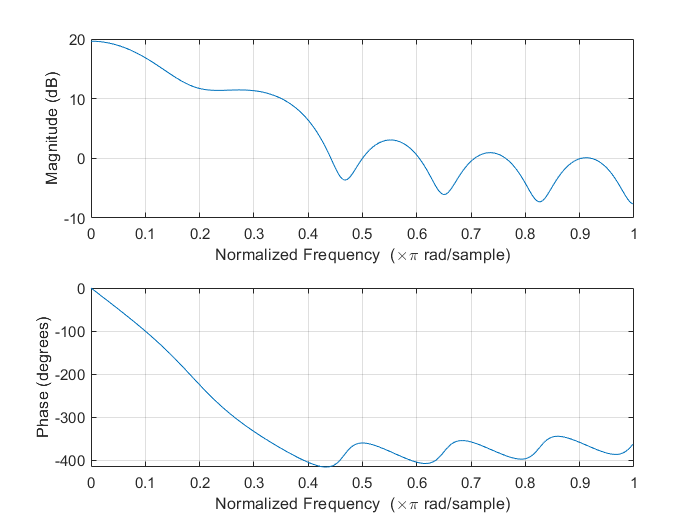

x3 = 1-sin(pi*(0:11)/4);
freqz(x3, 1)

## P8

Consider a noncausal finite length sequence x[n] = δ[n + 1] + δ[n] + δ[n − 1], we can compute the DTFT in MATLAB using following scripts:

x=[1 1 1]; % n=-1,0,1 

om=linspace(-pi, pi, 60); 

X1=dtft12(x, -1, om); X2=freqz(x, 1, om);

(a) Use subplot to plot the magnitude |X1|, |X2| and phase ∠X1, ∠X2 in one graph respectively.

close all; clear;
fprintf('8(a)\n');

8(a)


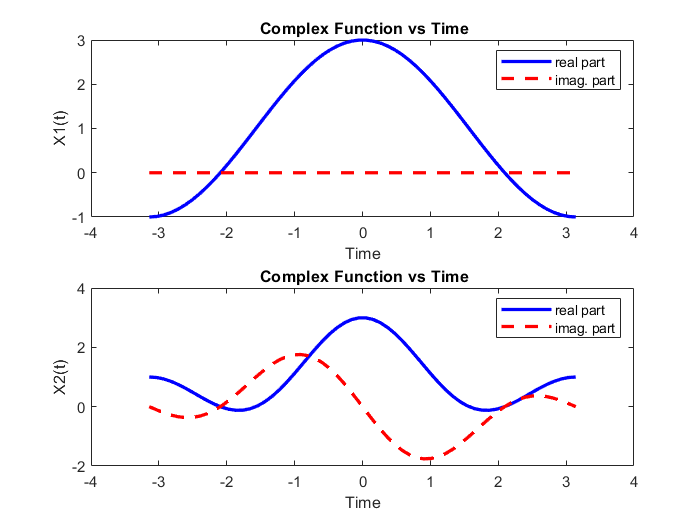

x=[1 1 1]; % n=-1,0,1 
om=linspace(-pi, pi, 60); 
X1=dtft12(x, -1, om); X2=freqz(x, 1, om);

figure;
subplot(2,1,1);
plot(om,real(X1),'b-','LineWidth',2);
hold on;
plot(om,imag(X1),'r--','LineWidth',2);
title('\bf Complex Function vs Time');
ylabel('X1(t)');
xlabel('Time');
legend('real part','imag. part');
hold off;
subplot(2,1,2);
plot(om,real(X2),'b-','LineWidth',2);
hold on;
plot(om,imag(X2),'r--','LineWidth',2);
title('\bf Complex Function vs Time');
ylabel('X2(t)');
xlabel('Time');
legend('real part','imag. part');
hold off;

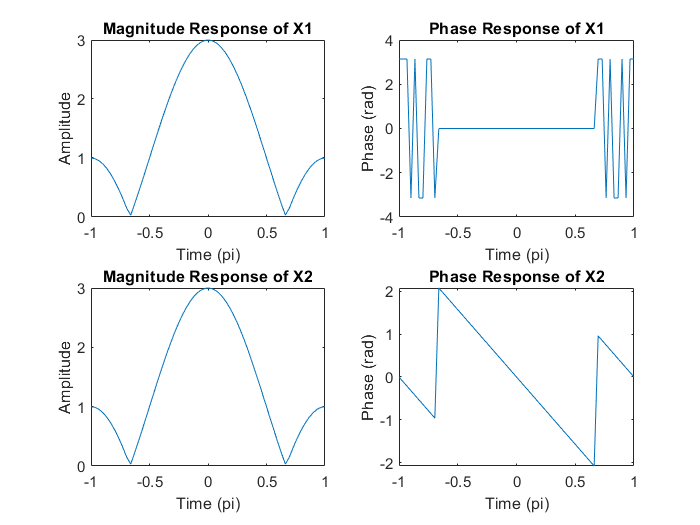


figure;
subplot(2,2,1); 
plot(om/pi, abs(X1));
title('Magnitude Response of X1');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,2);
plot(om/pi, angle(X1));
title('Phase Response of X1');
ylabel('Phase (rad)');
xlabel('Time (pi)');
subplot(2,2,3); 
plot(om/pi, abs(X2));
title('Magnitude Response of X2');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,4);
plot(om/pi, angle(X2));
title('Phase Response of X2');
ylabel('Phase (rad)');
xlabel('Time (pi)');

(b) Is the magnitude |X1| = |X2| ? Is the phase ∠X1 = ∠X2 ? If not, Explain. 

Ans.

[dtft12]

    function X=dtft12(x,Nstart,om)

    X=freqz(x,1,om);

    X=exp(-j*om*Nstart).*X;

Although the magnitude |X1| is equal to |X2|, the phase ∠X1 isn't equal to ∠X2. The reason is that function dtft12 do some phase shift to singal, this processing makes image part of signal become odd function.

## P9

In this problem use the image file “DSP.png” which has 100×300 pixels (unsigned 8 bits per pixel). You can use the following MATLAB script to load, show and store the image files:

img = imread('DSP.png'); 

imshow(img); 

imwrite(img, 'DSP0.png'); 

(a) Consider the 5×5 impulse response h[m, n] given as follow: 


$$h\left\lbrack m,n\right\rbrack =\left\lbrace \begin{array}{cc}
\frac{1}{25} & -2\le m,n\le 2\\
0 & \mathrm{otherwise}
\end{array}\right.$$


 filter the “DSP.png” using (2.78) and display the resulting image, comment on the result.

close all; clear;
fprintf('9(a)\n');

9(a)


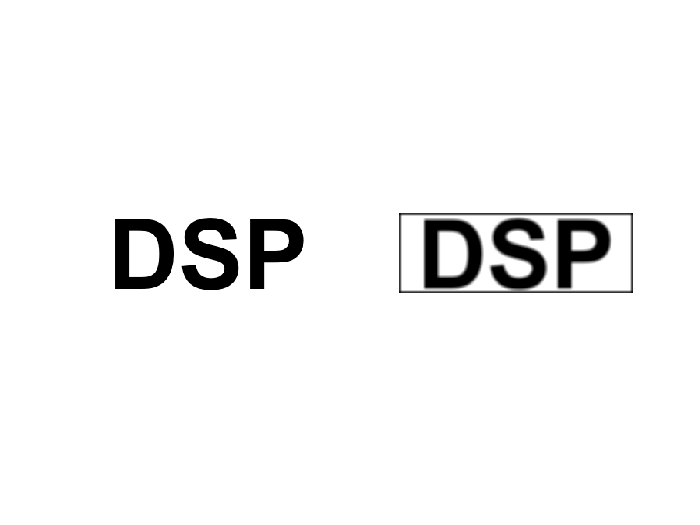

img = imread('DSP.png'); 
subplot(1,2,1);
imshow(img); 

subplot(1,2,2);
h = (1/25)*[1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1; 1 1 1 1 1];
img_dou = double(img);
img_conv = conv2(img_dou,h);
img_conv = uint8(img_conv);
imwrite(img_conv, 'DSP0.png');
imshow(img_conv);

The result is blurred than the original image since this processing is to average this kernel.  

(b) Repeat part (a) and try two different kernels ℎ1[m, n] and ℎ2[m, n]: (known as Sobel filter)


$$h_1 \left\lbrack m,n\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & -1\\
2 & 0 & -2\\
1 & 0 & -1
\end{array}\right\rbrack ,h_2 \left\lbrack m,n\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 2 & 1\\
0 & 0 & 0\\
-1 & -2 & -1
\end{array}\right\rbrack$$


what is the difference between the two results? (Hint: You should do abs and uint8 before imshow)

fprintf('9(b)\n');

9(b)


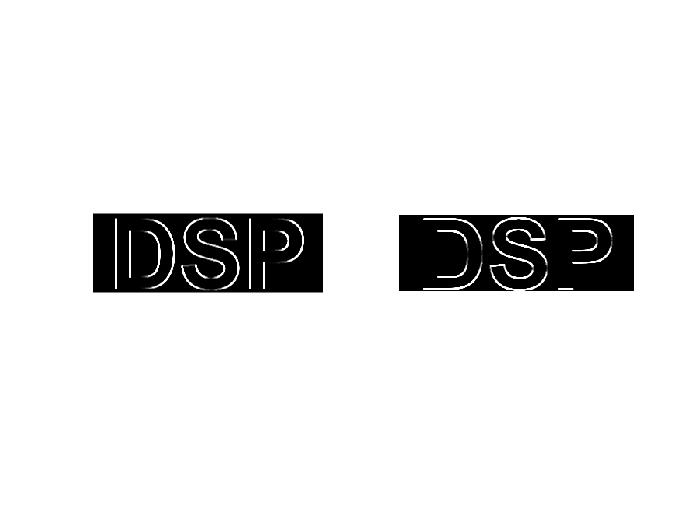

img_dou = double(img);

subplot(1,2,1);
h1 = [1 0 -1; 2 0 -2; 1 0 -1];
img1_conv1 = conv2(img_dou,h1);
img1_conv = abs(img1_conv1);
img1_conv = uint8(img1_conv);
imwrite(img1_conv, 'DSP1.png');
imshow(img1_conv);

subplot(1,2,2);
h2 = [1 2 1; 0 0 0; -1 -2 -1];
img2_conv1 = conv2(img_dou,h2);
img2_conv = abs(img2_conv1);
img2_conv = uint8(img2_conv);
imwrite(img2_conv, 'DSP2.png');
imshow(img2_conv);

For h1, this is looking for the vertical edge of this picture. And the matrix h1 show that we ignore the medium vector, and amplify the value of the boundary. If two color are the same, the value after convolution is zero. 

For h2, this is looking for the horizontal edge of this picture.

(c) Repeat (b) by using filter2 function, what is the difference between the two functions? (Hint: Check the pixel values before abs)

fprintf('9(c)\n');

9(c)


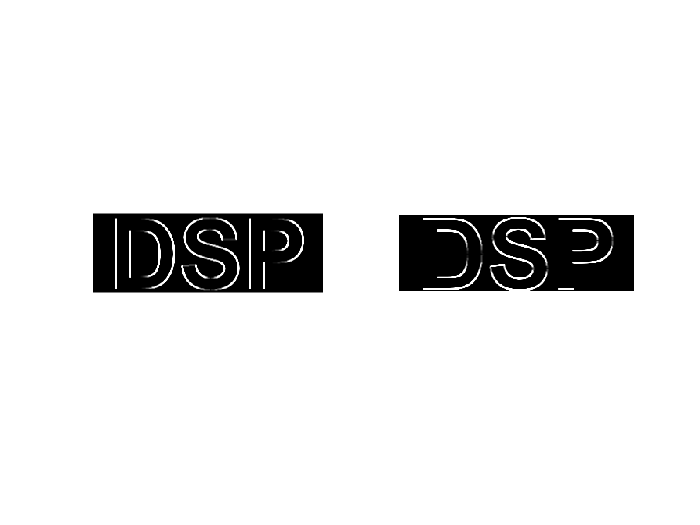

img1_filter1 = filter2(h1, img_dou);
img1_filter = abs(img1_filter1);
img1_filter = uint8(img1_filter);
imwrite(img1_filter, 'DSP1_filter.png');
imshow(img1_filter);

img2_filter1 = filter2(h2, img_dou);
img2_filter = abs(img2_filter1);
img2_filter = uint8(img2_filter);
imwrite(img2_filter, 'DSP2_filter.png');
imshow(img2_filter);


img1_conv1

img1_conv1 =          255         255           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
         765         765           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0  

img1_filter1

img1_filter1 =         -765           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
       -1020           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0

img2_conv1

img2_conv1 =          255         765        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020
         255         765        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020        1020  

img2_filter1

img2_filter1 =         -765       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020       -1020
           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0

After comparing the results come from function "conv2" and "filter2", I find that the sign of this two results are opposite.

## P10

This problem uses the sound file “handel.wav” available in MATLAB. This sound is sampled at Fs = 8192 samples per second using 8-bits per sample. You can use the following MATLAB script to load, play and store the audio files:

close all; clear;
[y,Fs] = audioread('handel.wav'); 
playerObj = audioplayer(y, Fs); 
play(playerObj); 
audiowrite('handel0.wav', y, Fs);

(a) Select every other sample in audio signal y which reduces the sampling rate by a factor of two. Now listen to the new sound array using the sound function at half the sampling rate. (Hint: You can use the logical array to index array elements) 

y2 = y(1:2:end); % Select every second sample in audio signal y
playerObj = audioplayer(y2, Fs/2); % sampling rate / 2
play(playerObj); 
audiowrite('handel1.wav', y2, Fs/2);

(b) Select every fourth sample in audio signal y which reduces the sampling rate by a factor of four. Listen to the resulting sound array using the sound function at quarter the sampling rate.

y4 = y(1:4:end); % Select every fourth sample in audio signal y
playerObj = audioplayer(y4, Fs/4); % sampling rate / 4
play(playerObj); 
audiowrite('handel2.wav', y4, Fs/4);

(c) From the results of (a) and (b), what do you discover?

Ans:

I find that the sound quality decreases as the sample rate drops.